## Cone-1

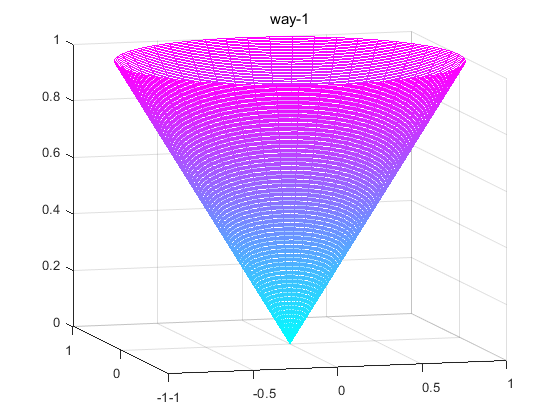

clc;
figure('name', 'cone-1', 'color', 'w');
r = linspace(0, 1, 200);
th = linspace(0, 2 * pi, 50);
[R, T] = meshgrid(r, th);
X = R .* cos(T);
Y = R .* sin(T);
Z = R;
mesh(X, Y, Z,'FaceAlpha','0.5')
colormap(cool(50))
title('way-1')

## Cone-2

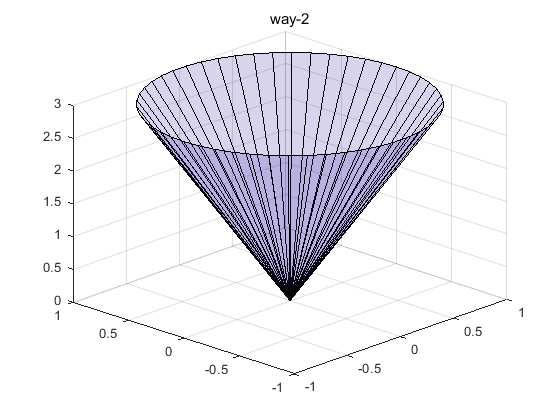

figure('name', 'cone-1', 'color', 'w');
R = 1; %// radius
H = 3; %// height
N = 50; %// number of points to define the circumference
[x, y, z] = cylinder([0 R], N);
surf(x, y, H * z,'FaceAlpha','0.2')
title('way-2')

## Cone-3

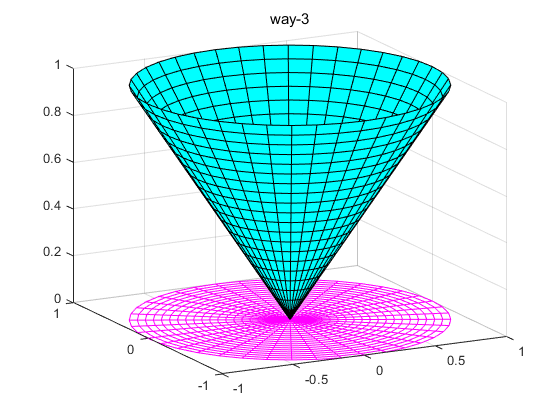

figure('name', 'cone-1', 'color', 'w');
z = cplxgrid(20); %在复平面上面得到一个21*41的网格，x，y分别为其实部和虚部
x = real(z);
y = imag(z);
fz = sqrt((x.^2 + y.^2)); %圆锥公式，z^2=x^2+y^2来求fz
cplxmap(z, fz) %作图
colormap(cool(50))
title('way-3')

## 绘制任意朝向的圆锥函数-1

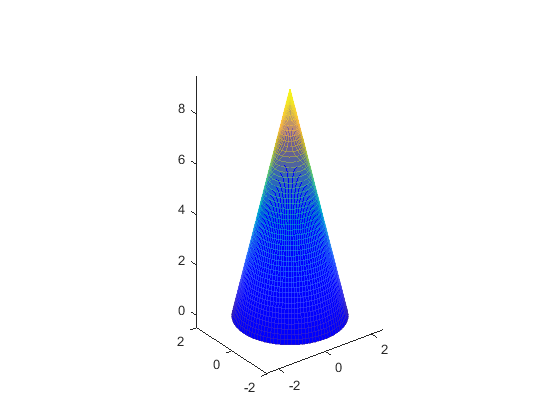

figure('name', 'cone-1', 'color', 'w');
cone3([0,0,0],[0,0,9],2,'b')

### function cone3(X1,X2,r,color)

function cone3(X1,X2,r,color)
%一个简单的例子：cone3([1 2 3],[7 8 9],1,'b');%两个空间点位置，圆锥底面半径，颜色
% 圆锥的高度
length_cyl=norm(X2-X1);
[x,y,z]=cylinder(linspace(r,0,50),100);
z=z*length_cyl;
%绘制圆锥底面
hold on;
EndPlate1=fill3(x(1,:),y(1,:),z(1,:),'c');
Cylinder=mesh(x,y,z);
%计算圆锥体旋转的角度
unit_V=[0 0 1];
angle_X1X2=acos(dot( unit_V,(X2-X1) )/( norm(unit_V)*norm(X2-X1)) )*180/pi;
%计算旋转轴
axis_rot=cross(unit_V,(X2-X1));
%将圆锥体旋转到期望方向
if angle_X1X2~=0 % Rotation is not needed if required direction is along X
    rotate(Cylinder,axis_rot,angle_X1X2,[0 0 0])
    rotate(EndPlate1,axis_rot,angle_X1X2,[0 0 0])
end
%将圆锥体和底面挪到期望的位置
set(EndPlate1,'XData',get(EndPlate1,'XData')+X1(1))
set(EndPlate1,'YData',get(EndPlate1,'YData')+X1(2))
set(EndPlate1,'ZData',get(EndPlate1,'ZData')+X1(3))
set(Cylinder,'XData',get(Cylinder,'XData')+X1(1))
set(Cylinder,'YData',get(Cylinder,'YData')+X1(2))
set(Cylinder,'ZData',get(Cylinder,'ZData')+X1(3))
% 设置圆锥体的颜色
set(Cylinder,'FaceColor',color)
set(EndPlate1,'FaceColor',color)
set(Cylinder,'EdgeAlpha',0.5)
set(EndPlate1,'EdgeAlpha',0.5)
axis equal;
view(3)
end